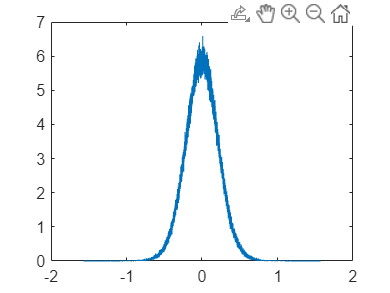

n = 1e6;
range = zeros(1,n);
sigma = 0.3/sqrt(2);
for ii = 1:n
    x = normrnd(0, sigma);
    y = normrnd(0, sigma);
    alpha = atan(y/(1-x));
    index = floor((alpha+pi/2)/(pi/n));
    range(index) = range(index) + 1;
end
range1 = zeros(1,n-200);
for ii = 101:n-100
    range1(ii-100) = sum(range(ii-100:ii+100))/201;
end
range1 = range1/sum(range1)*(n-199);
axis = linspace(-pi/2+pi*1e-4, pi/2-pi*1e-4, n-200);
plot(axis, range1);